# Load Network

load('net/net1/fastercnn.mat');
disp(trainedDetector);

  fasterRCNNObjectDetector with properties:

        ModelName: 'BudweiserLata'
          Network: [1×1 DAGNetwork]
      AnchorBoxes: [3×2 double]
       ClassNames: {1×8 cell}
    MinObjectSize: [15 15]



## Get Frames

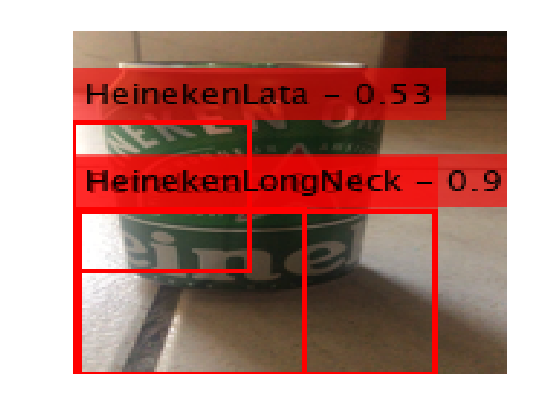

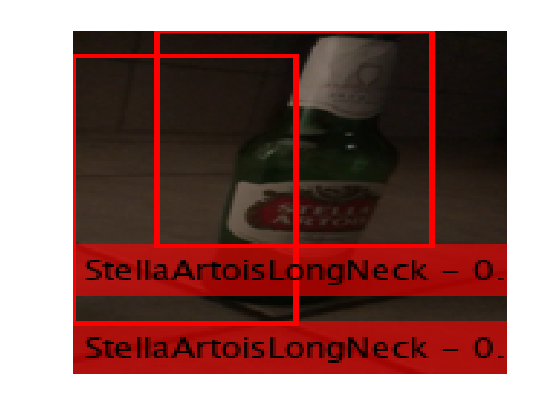

videor = VideoReader('validationVideo/validate_2.MOV');

currAxes = axes;
while hasFrame(videor)
    frame = readFrame(videor);
    frame = imresize(frame,[150,150]);
    
    [bbox, score, label] = detect(trainedDetector,frame);
    label_str = cell(size(bbox,1),1);
    
    if size(bbox,1) > 0
        for i=1:size(bbox,1)
            label_str{i} = [char(label(i)) ' - ' num2str(score(i),'%0.2f')];
        end
        
        detectedImg = insertObjectAnnotation(frame,'rectangle',bbox,label_str,'LineWidth',2,'Color','r');
    end    
    
    image(detectedImg,'Parent',currAxes);
    currAxes.Visible = 'off';
    pause(1/videor.FrameRate);

end

## Get Frame to Validate

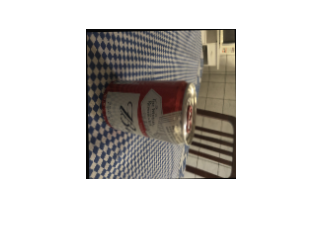

frame = imread('Dataset/BudweiserLata/img_230.png');

figure; 
imshow(frame);

[bbox, score, label] = detect(trainedDetector,frame)

bbox =      1    69    58    75
    16    52    95    67


score = 2×1 single column vector
    0.5785
    0.8410


label = 2×1 categorical array
     PetraLongNeck 
     PetraLongNeck 


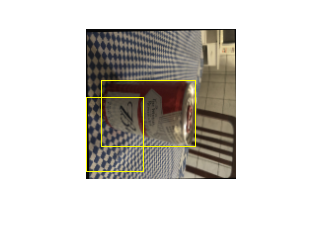

detectedImg = insertShape(frame,'Rectangle',bbox);
figure;
imshow(detectedImg)